## SIR Model Equations


$$\Delta I_t = \beta \times I_t \times S_t \times \lambda u\\
\Delta R_t = \gamma \times I_t \\
\Delta S_t = \alpha \times R_t \\
S_{t+1} = S_t - \Delta I_t + \Delta S_t\\
I_{t+1} = I_t + \Delta I_t - \Delta R_t \\
R_{t+1} = R_t + \Delta R_t - \Delta S_t\\$$



$$\frac{dS}{dt} = -\beta \times I_t \times S_t + \alpha \times R\\
\frac{dI}{dt} = \beta \times I_t \times S_t \times \lambda u - \gamma \times I_t \\
\frac{dR}{dt} = \gamma \times I_t - \alpha \times R_t \\$$


% Initialization
s_0 = 99;
i_0 = 1;
r_0 = 0;

beta = 1 / 90;
gamma = 1 / 2;
alpha = 0.04;

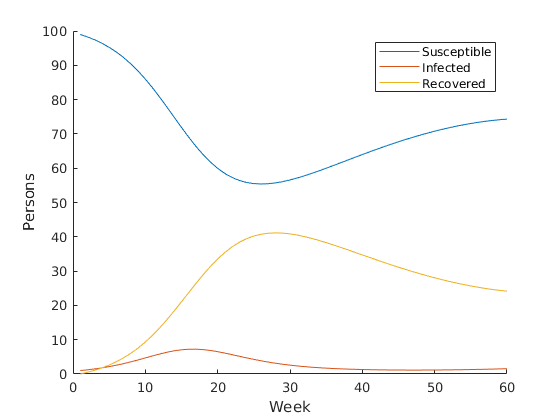

lambda =0.54;
control = 0.64;

% Run simulation
[S, I, R, W] = model_simulate(s_0, i_0, r_0, beta, gamma, alpha, lambda, control, 60);

% Plot
figure(1); clf; hold on;
plot(W, S); label1 = "Susceptible";
plot(W, I); label2 = "Infected";
plot(W, R); label3 = "Recovered";

xlabel("Week")
ylabel("Persons")
legend({label1, label2, label3})